% way0 = [0, 275/2];
% way2 = [450, 275];
% way1 = [450, 275/2-10]
t = 0:0.001:1;

% wayx = way1(1) + (way0(1)-way1(1))*(1-t).^2 + (way2(1)-way1(1))*t.^2;
% wayy = way1(2) + (way0(2)-way1(2))*(1-t).^2 + (way2(2)-way1(2))*t.^2;


P0 = [0, 0];
% P2 = [100, 200];

P2x = 450;
P2y = 450;
P2 = [P2x, P2y];

P1x =-242;
P1y =85;
P1 = [P1x, P1y];

ang = atan2d(P2(2)-P0(2), P2(1)-P0(1));
des_head = 3.2;


start_head = -67;
format short;
bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;

angle = atan2d(by(1000)-by(999), bx(1000)-bx(999));
% disp('Final End Heading = ');
if angle > 90
    angle= angle-180;
end
% des_head=angle;

l_y = P2(2)+10*sind(des_head);
l_x = P2(1)+10*cosd(des_head);
x = -200:10:1000;

m = (l_y-P2(2))/(l_x-P2(1));
b = P2(2)-m*P2(1);
y = m.*x+b;

s_y = P0(2)+100*sind(start_head);
s_x = P0(1)+100*cosd(start_head);
x2 = 0:1:x(1);
m2 = (s_y-P0(2))/(s_x-P0(1));
b2 = P0(2)-m2*P0(1);
y2 = m2.*x2+b2;

if m ~= m2
    x_intersect = (b2 - b) / (m - m2);
    y_intersect = m * x_intersect + b;

    % fprintf('Intersection point: (%.2f, %.2f)\n', x_intersect, y_intersect);
else
    disp('The lines are parallel and do not intersect.');
end
% 

% 
P1y = y_intersect;
P1x = x_intersect;
P1 = [P1x, P1y];
bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;
f_angle = atan2d(by(1000)-by(999), bx(1000)-bx(999));
disp('Final End Heading = ');

Final End Heading = 


if f_angle > 90
    f_angle= angle-180;
end
disp(f_angle)

    3.2582



disp('Desired End Heading = ');

Desired End Heading = 


disp(des_head)

    3.2000



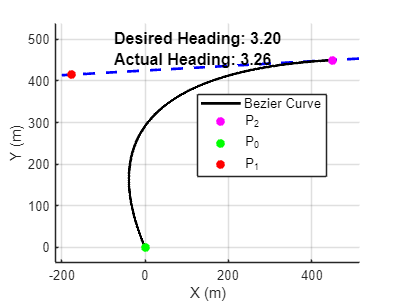


angle = atan2d(by(2)-by(1), bx(2)-bx(1));
if angle > 90
    angle= angle-180;
end
% disp('Final Start Heading = ')
% disp(angle)
% disp('Desired Start Heading = ');
% disp(start_head)

close;
% ylim([-200, 600]);
% xlim([-200, 600])
xlim([-143 588])
ylim([-74 502])
% figure();
% clear;
hold on;
% scatter([way0(1), way1(1), way2(1)], [way0(2), way1(2), way2(2)], 'MarkerFaceColor', 'k')


% plot([P0(1), s_x], [P0(2), s_y], 'LineWidth', 2, 'Color', 'k', 'LineStyle','--')
axis('equal');
% plot([way1(1), P1(1)], [way1(2), P1(2)], 'LineWidth', 2)
% plot(wayx, wayy, 'LineWidth', 2, 'Color', 'k')
% plot([P1(1), way1(1)], [P1(2), way1(2)])
plot(x, y, 'LineWidth', 2, 'Color', 'blue', 'LineStyle','--')
% plot(x2, y2, 'LineWidth', 2, 'Color', 'blue', 'LineStyle','--')
plot(bx, by, 'LineWidth', 2, 'Color', 'black')
scatter(P2(1), P2(2), 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor','magenta')
scatter(P0(1), P0(2), 'MarkerFaceColor', 'green', 'MarkerEdgeColor','green')
scatter(P1x, P1y, 'MarkerFaceColor', 'red', 'MarkerEdgeColor','red')
legend('', 'Bezier Curve', 'P_2', 'P_0', 'P_1', fontsize=10)
text(-75, 500, sprintf('Desired Heading: %.2f', des_head), FontWeight='bold', FontSize=12)
text(-75, 450, sprintf('Actual Heading: %.2f', f_angle), FontWeight='bold', FontSize=12)
xlabel('X (m)')
ylabel('Y (m)')
grid('on')
hold off;



% P0 = [-82.2, 39.596];
% P2 = [-82.19829, 39.59865];
%
% P1x =-82.2
% P1y =39.597
% P1 = [P1x, P1y];
%
% t = 0:0.01:1;
% bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
% by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;
%
% angle = atan2d(by(101)-by(100), bx(101)-bx(100));
% disp('Final angle = ');
% disp(angle)
%
% figure(1)
%
% scatter(P1x, P1y, 'MarkerFaceColor', 'red')
% hold on;
% axis('equal')
% plot(bx, by, 'LineWidth', 2, 'Color', 'blue')
% plot(Waypts(1,:), Waypts(2,:), 'LineWidth', 2, 'Color', 'k')
% hold off;

